# **PART 2: Modeling**

clear all
clc

# Exercise 2.1

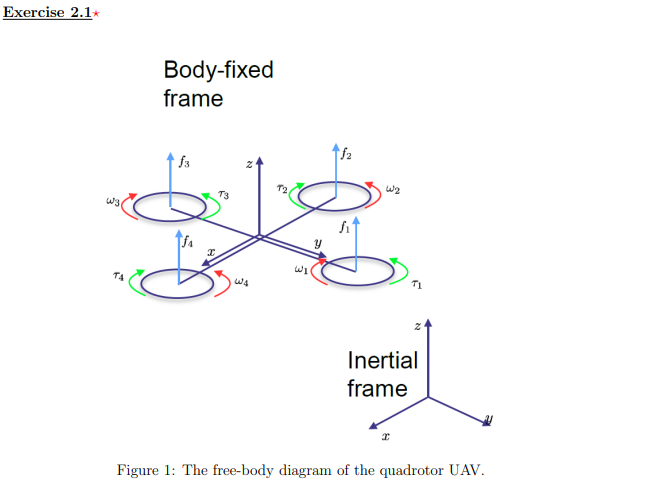

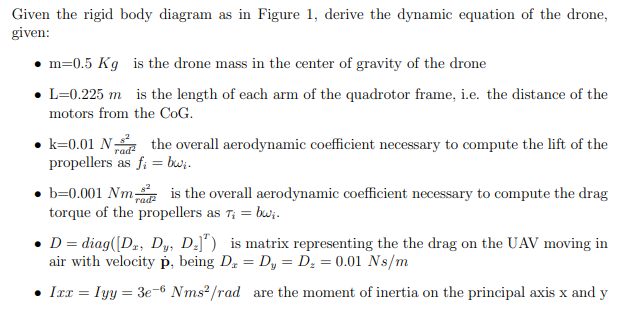

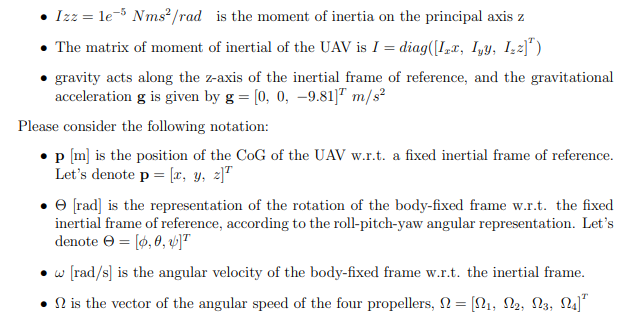

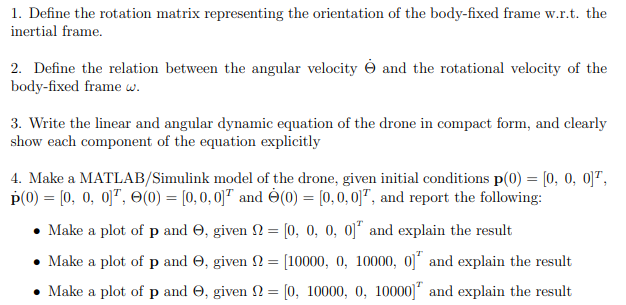

syms x y z phi theta psi theta_dot phi_a
m=0.5;    % m=0.5 Kg 
L=0.225;  %L=0.225 m 
k=0.01 ;  %N(s^2/rad^2)
b=0.001; %Nm(s^2/rad^2)
D=diag([0.01,0.01,0.01]'); %Ns/m
Ixx=3*exp(-6);   %Nm(s^2/rad)
Iyy=3*exp(-6);   %Nm(s^2/rad)
Izz=1*exp(-5);   %Nm(s^2/rad)
I=diag([Ixx,Iyy,Izz]');
g=[0,0,-9.81]';  %m/s
%p_m=[x,y,z]'
%Theta=[phi,theta,psi]'


%1.
%Rotaion=rz*ry*rx
rotx = [1, 0, 0; 0, cos(phi), -sin(phi); 0, sin(phi), cos(phi)];
roty = [cos(theta), 0, sin(theta); 0, 1, 0; -sin(theta), 0, cos(theta)];
rotz = [cos(psi), -sin(psi), 0; sin(psi), cos(psi), 0; 0, 0, 1];

Rotation=[cos(psi)*cos(theta) cos(psi)*sin(theta)*sin(phi)-sin(psi)*cos(theta) cos(psi)*sin(theta)*cos(phi)+sin(psi)*sin(theta);...
          sin(psi)*cos(theta) sin(psi)*sin(theta)*sin(phi)-cos(psi)*cos(theta) sin(psi)*sin(theta)*cos(phi)+cos(psi)*sin(theta);...
          -sin(theta) cos(theta)*sin(phi) cos(theta)*cos(phi)]

$$Rotation = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{2} & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\sigma_{1} & \sin\left(\psi \right)\,\sin\left(\theta \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \sigma_{1} & \sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\sigma_{2} & \cos\left(\psi \right)\,\sin\left(\theta \right)+\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sigma_{2}=\cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}$$


%rotz*roty*rotx

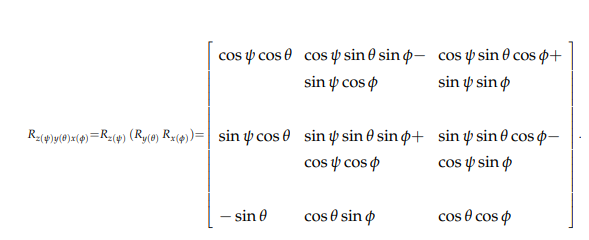

%2.
w_arrow=[1 0 -sin(theta); 0 cos(phi) cos(theta)*sin(phi); 0 -sin(phi) cos(theta)*cos(phi)]%*theta_dot

$$w\_arrow = \left(\begin{array}{ccc} 1 & 0 & -\sin\left(\theta \right)\\ 0 & \cos\left(\varphi \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right)\\ 0 & -\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

%3. 
syms i w x_dot y_dot z_dot k_d R w1 w2 w3 w4 wx wy wz
F_B=k*[0;0;symsum(w^2,i,1,4)]

$$F\_B = \left(\begin{array}{c} 0\\ 0\\ \frac{w^{2}}{25} \end{array}\right)$$

F_D=-k_d*[x_dot;y_dot;z_dot] % what exactly is kd

$$F\_D = \left(\begin{array}{c} -k_{d}\,\dot{x}\\ -k_{d}\,\dot{y}\\ -k_{d}\,\dot{z} \end{array}\right)$$

%linear dynamics equation
x_ddot=(-m*g+R*F_B+F_D)/m

$$x\_ddot = \left(\begin{array}{c} -2\,k_{d}\,\dot{x}\\ -2\,k_{d}\,\dot{y}\\ \frac{2\,R\,w^{2}}{25}-2\,k_{d}\,\dot{z}+\frac{981}{100} \end{array}\right)$$

%angular dynamics equation
tau_b_phi=L*k*(w1^2-w3^2);
tau_b_theta=L*k*(w2^2-w4^2);
tau_b_psi=b*(w1^2-w3^2+w2^2-w4^2);

w_dot_x=tau_b_phi*(Ixx^-1)-(((Iyy-Izz)/Ixx)*wy*wz);
w_dot_y=tau_b_theta*(Iyy^-1)-(((Izz-Ixx)/Iyy)*wx*wz);
w_dot_z=tau_b_psi*(Izz^-1)-(((Ixx-Iyy)/Izz)*wx*wy);
w_dot=vpa([w_dot_x;w_dot_y;w_dot_z])

$$w\_dot = \left(\begin{array}{c} 0.30257159511955133268656936706975\,{w_{1}}^{2}-0.30257159511955133268656936706975\,{w_{3}}^{2}-0.09390605718031828919034609270966\,\mathrm{wy}\,\mathrm{wz}\\ 0.30257159511955133268656936706975\,{w_{2}}^{2}-0.30257159511955133268656936706975\,{w_{4}}^{2}+0.09390605718031828919034609270966\,\mathrm{wx}\,\mathrm{wz}\\ 148.41315910257659993476408999413\,b\,\left({w_{1}}^{2}+{w_{2}}^{2}-1.0\,{w_{3}}^{2}-1.0\,{w_{4}}^{2}\right) \end{array}\right)$$

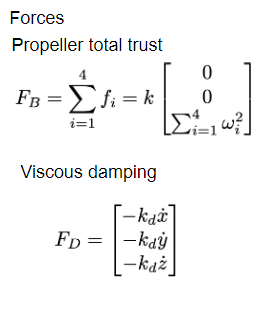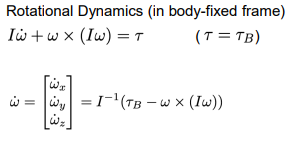

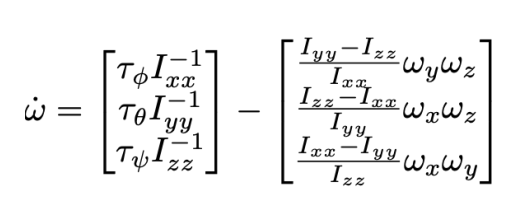

%4.
syms a b c d
p_0=[0 0 0]';
p_dot_0=[0 0 0]';
theta_0=[0 0 0]';  
theta_dot_0=[0 0 0]'; 

%omega=[0;0;0;0]'
%omega=[10000;0;10000;0]'
omega=[0;10000;0;10000]'

omega =            0       10000           0       10000



w_solve=subs(w_arrow,[theta phi],[theta_0(1) theta_0(2)])

$$w\_solve = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

tau_b_phi=subs(tau_b_phi,[w1 w3],[omega(1) omega(3)]);
tau_b_theta=subs(tau_b_theta,[w2 w4],[omega(2) omega(4)]);
tau_b_psi=subs(tau_b_psi,[w1 w2 w3 w4],[omega(1) omega(2) omega(3) omega(4)]);
tau_b=[tau_b_phi;tau_b_theta;tau_b_psi]

$$tau\_b = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

w_dot=(inv(I))*(tau_b-cross(w_solve,I*w_solve))

$$w\_dot = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$



F_B=k*[0;0;(omega(1)+omega(2)+omega(3)+omega(4))]

F_B =      0
     0
   200


F_D=-k_d*[p_dot_0(1);p_dot_0(2);p_dot_0(3)] % what exactly is kd

$$F\_D = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

%linear dynamics equation
mx_ddot=-m*g+R*F_B+F_D

$$mx\_ddot = \left(\begin{array}{c} 0\\ 0\\ 200\,R+\frac{981}{200} \end{array}\right)$$

w_solve

$$w\_solve = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

I*w_solve

$$ans = \left(\begin{array}{ccc} \frac{8573420067209025}{1152921504606846976} & 0 & 0\\ 0 & \frac{8573420067209025}{1152921504606846976} & 0\\ 0 & 0 & \frac{3884161996073403}{576460752303423488} \end{array}\right)$$

cross(w_solve,I*w_solve)

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

# Exercise 2.2

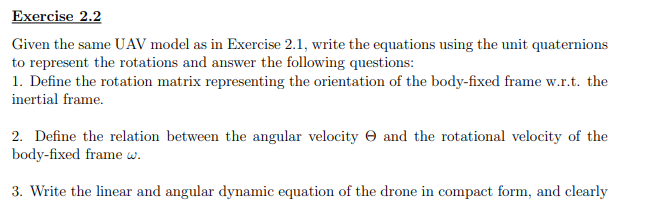

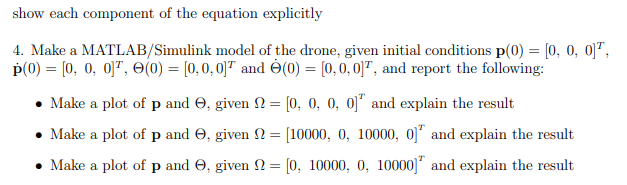

# Exercise 2.3